# Lab Assignment : Controller Design

## Part 3 : Validation

Based on the given requirements, write a script that validate the system according to all requirements. 

Write a thorough, yet concise report on methods of validating your system. 

### Author 

- Kantaka    Sirithanarattanakul    ID : 62340500002

- Keedita     Chaihetphon              ID : 62340500003

- Pakapak   Silpapinun                  ID : 62340500042

**Date **: 24 June 2021

### Description

In this part, validating the system due to the requirements is taken place by using the designed controller from part 2. To complete the assignment, 9 requirements are needed to be checked by using scope to observe the response plant's signal.

The designed controller is used to test and validate all of requirements as shown in figure 1.

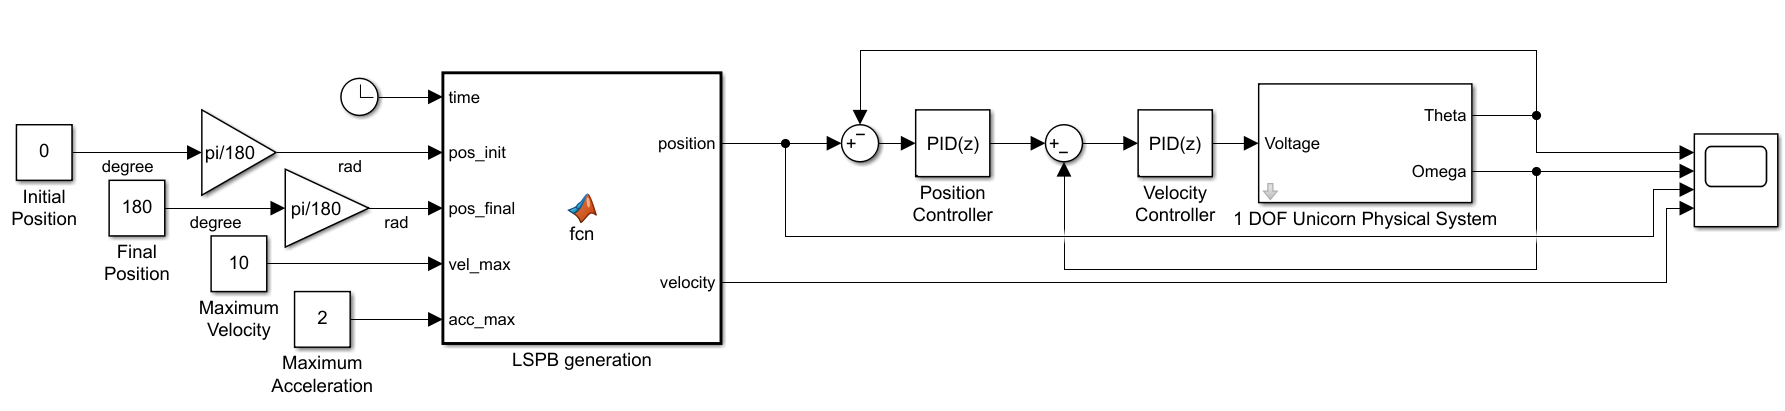

Figure 1 : Designed controller with plant

**For the first requirement : the user shall input a desired position.**

    According to figure 1, initial position and final position on your left-hand side are constant blocks which means the inital and final position is changable. However, due to the limitation of given virtual plants, the initial position is fixed at 0. Though the initial position is unchangable, we can conclude that the user shall input a desired position which completes the requirement.

**For the second requirement : the movement must  be bi-directional. **

    To explain the word 'bi-directional', it means the system can move both clockwise and counterclockwise. We tested this requirement by entering the value  both positive and negative as you can see in figure 2 and figure 3.

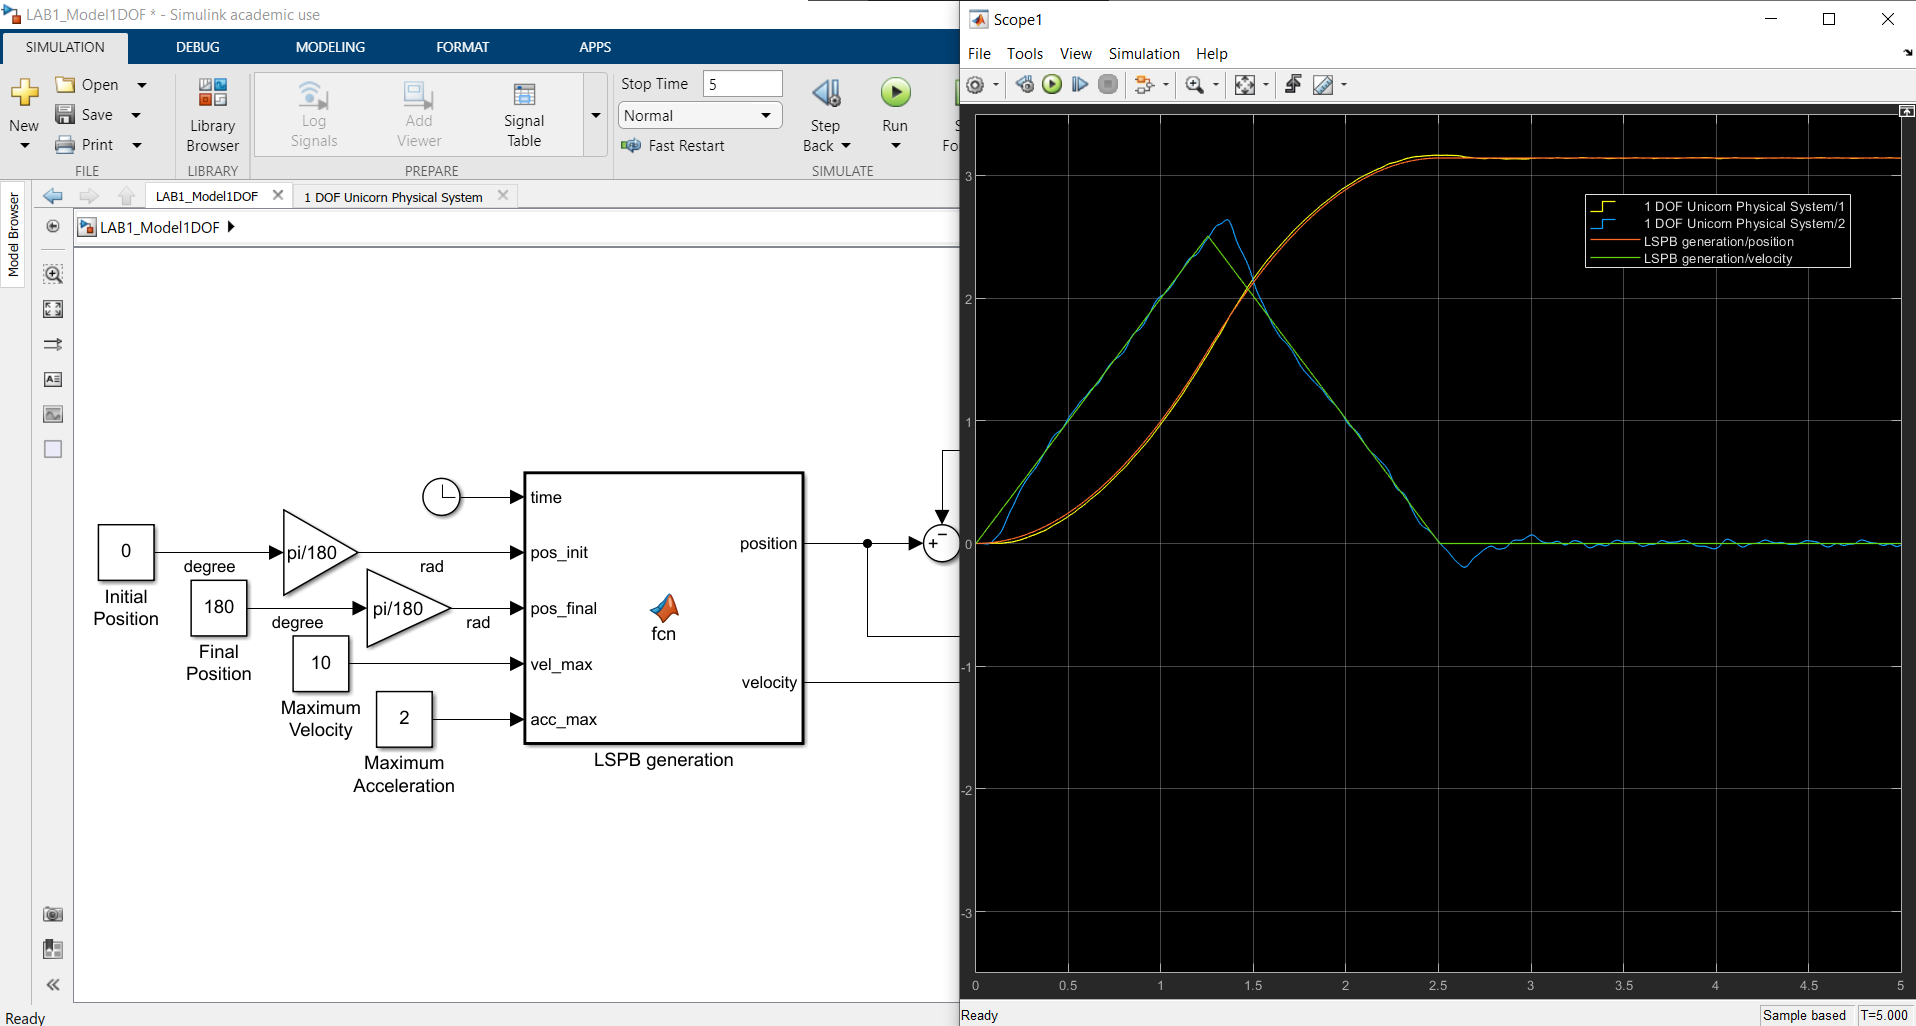

Figure 2: The result when value of final position is positive.

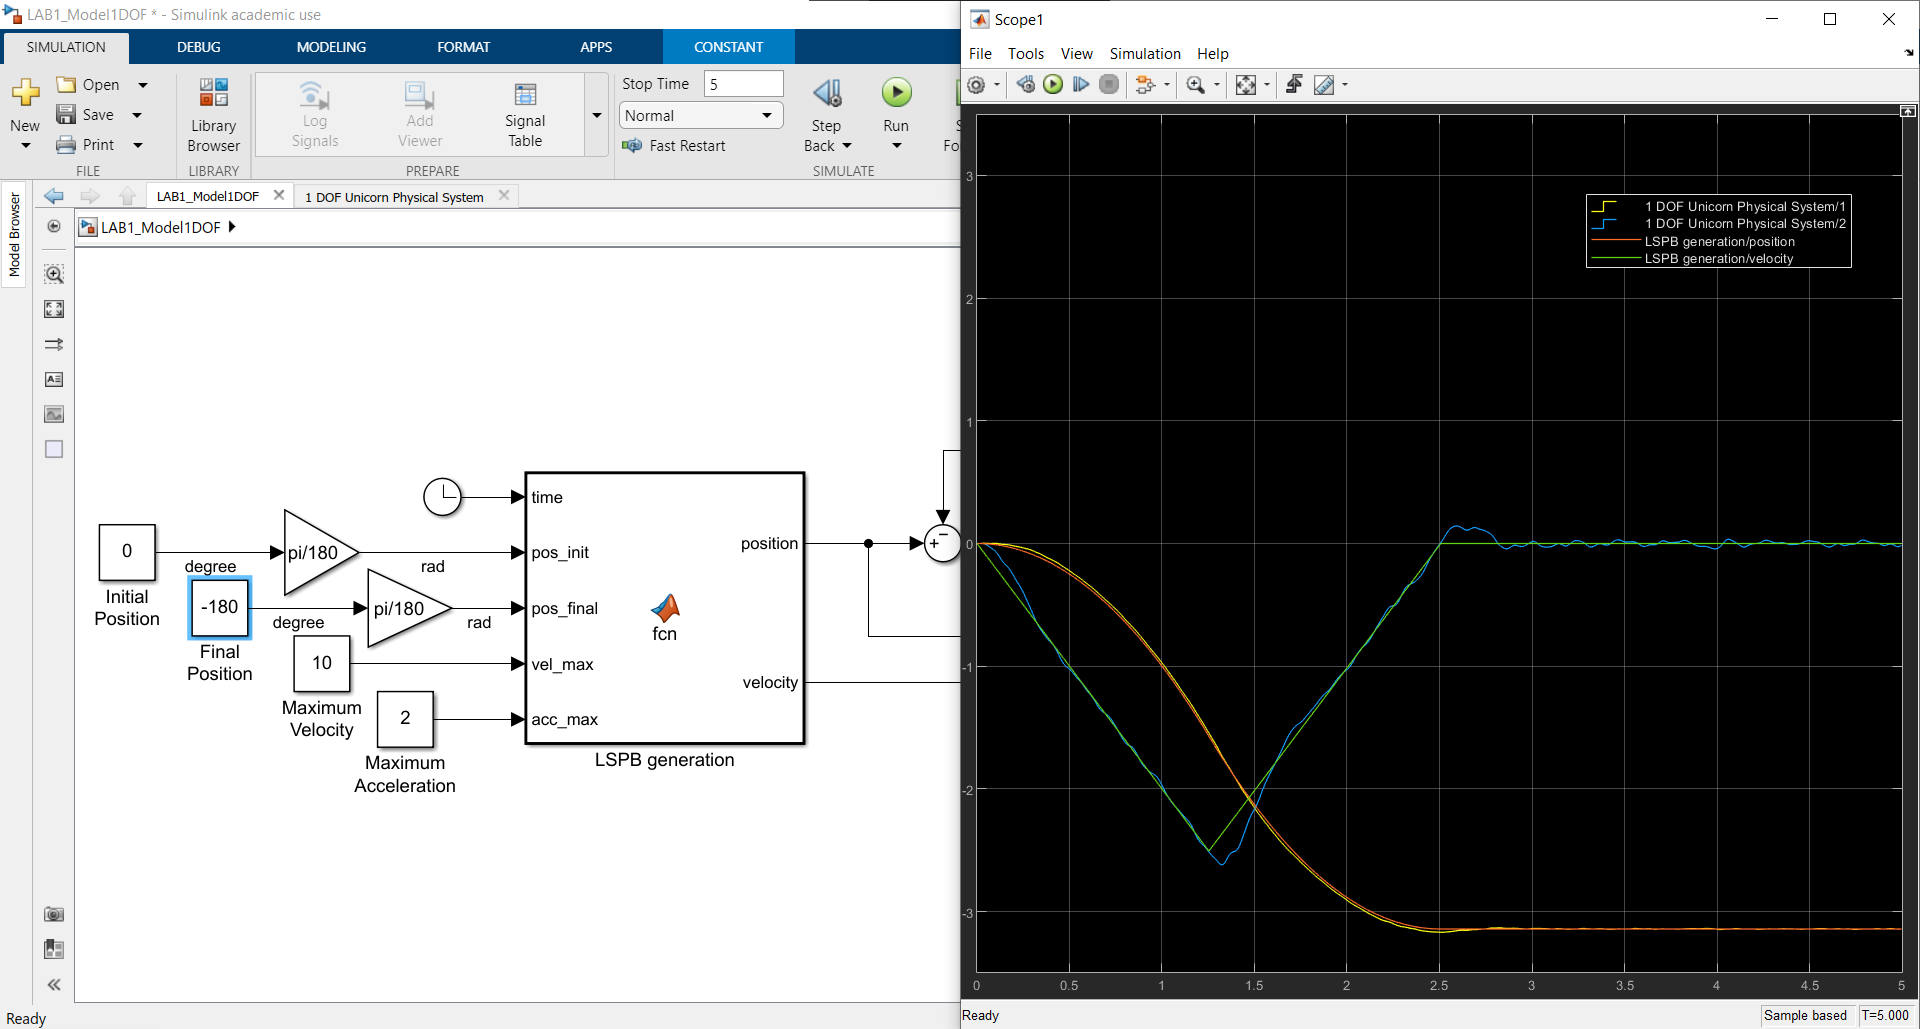

Figure 3: The result when value of final position is negative.

    From the result in figure 2 and figure 3, we can conclude that the system's movement is bi-directional which completes the requirement.

**For the third requirement :** **the movement varies between -180 degrees and 180 degrees.**

    To explain this requirement, we can rewrite into this 'the movement varies in [-180, 180] degree' which mean the out of range of input, the system must not work.

    Code in MATLAB function block has the condition as following to prevent exceed input's range.

    We can conclude that the system's movement varies between -180 degrees and 180 degrees which completes the requirement.

**For the fourth requirement : maximum achievable speed is 12.5 rad/s.**

    To test the maximum achievable speed of the system, we change the initial position in the plant's setting to -180 degrees. Then we set the final position value to 180 degrees. This will enlarge the maximum traveled distiance to be 360 degrees or $2\pi \;\textrm{rad}$. The result is shown in figure 4.

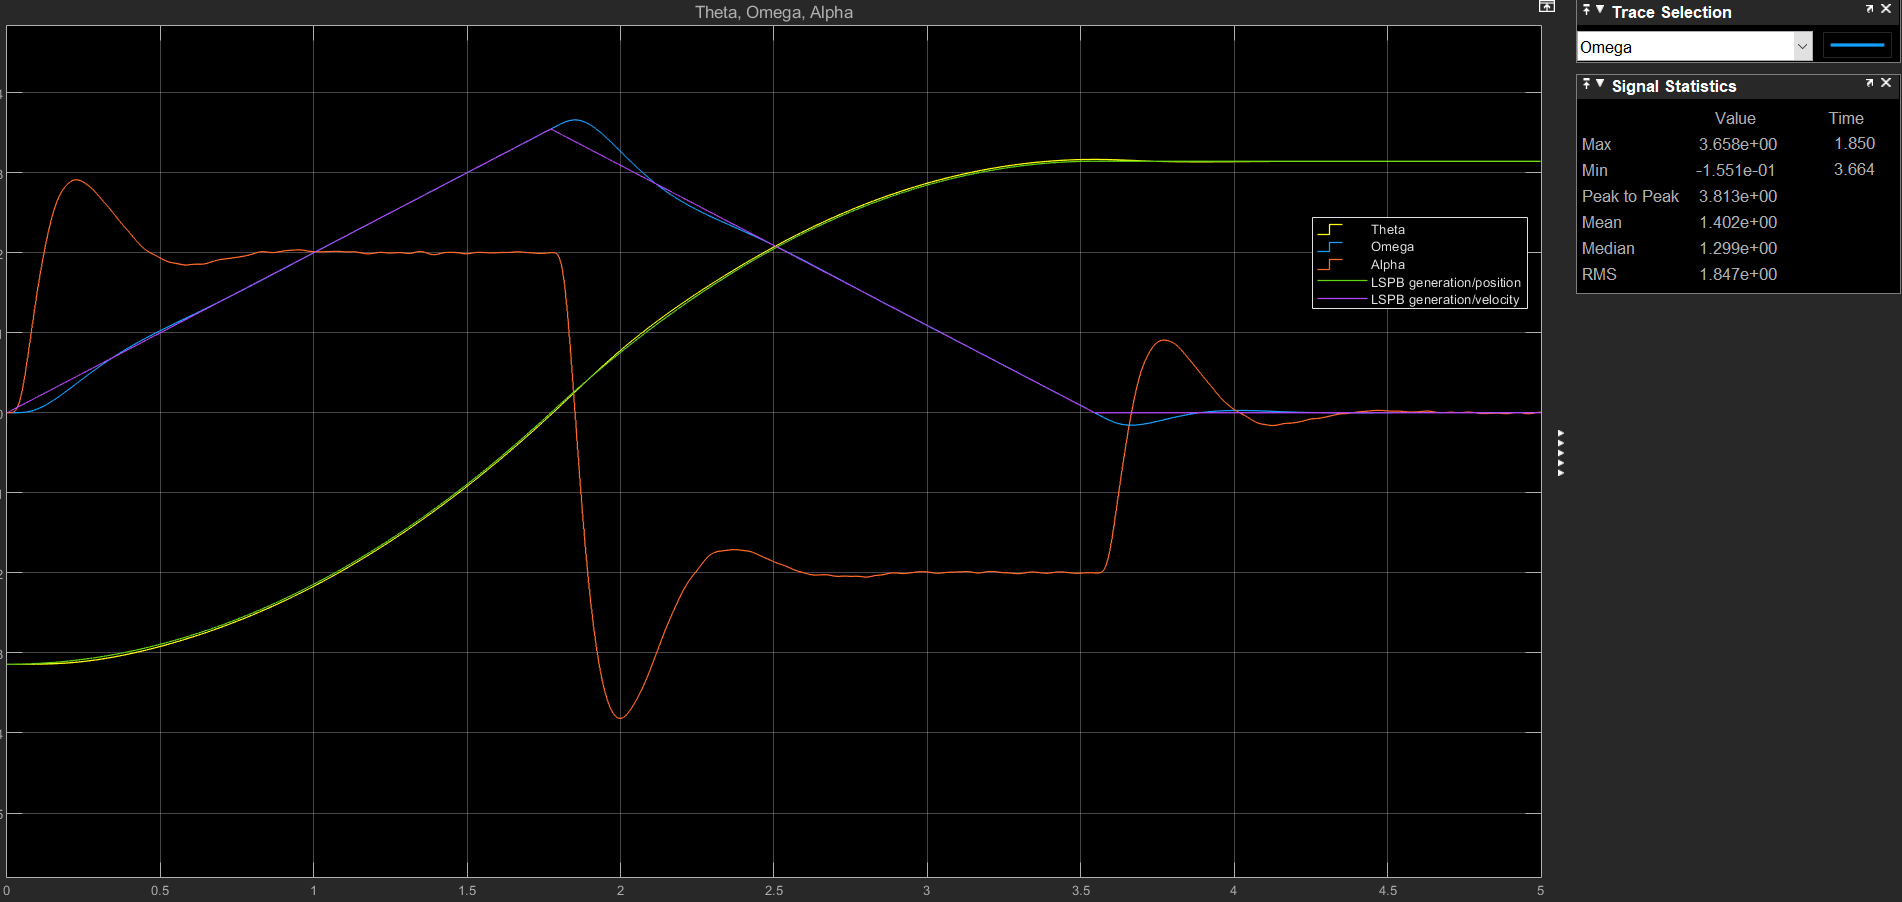

Figure 4 : Captured the response signal of angular velocity when traveled distance = $2\pi \;\textrm{rad}$

    According to figure 4, the maximum speed is 3.658 $\left(\textrm{rad}/s\right)$ when traveled distance is $2\pi \;\textrm{rad}$. From this result we can not conclude that the system has maximum achievable speed is 12.5 $\left(\textrm{rad}/s\right)$, so we focus on only virtual plant instead. We connect 1 constant block, represent for nominal voltage which is 12 V directly to virtual plant then measure the maximum angular velocity that made by this virtual plant as shown in figure 5 and figure 6.

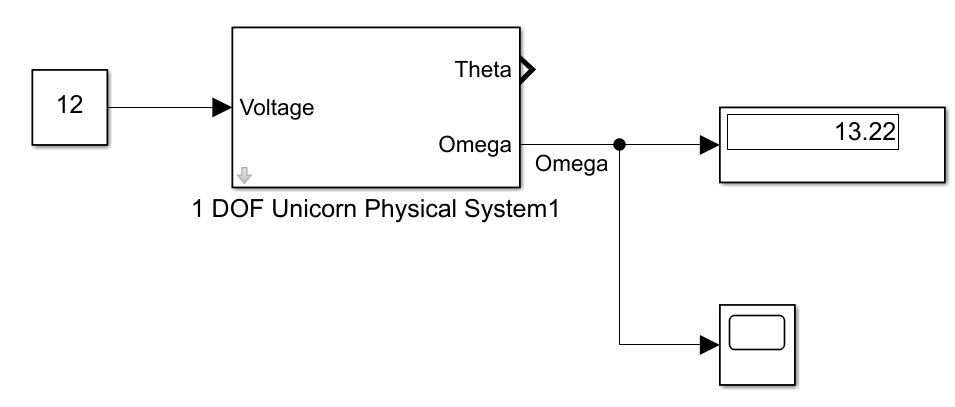

Figure 5 : the simulink model to measure the maximum angular velocity at maximum voltage

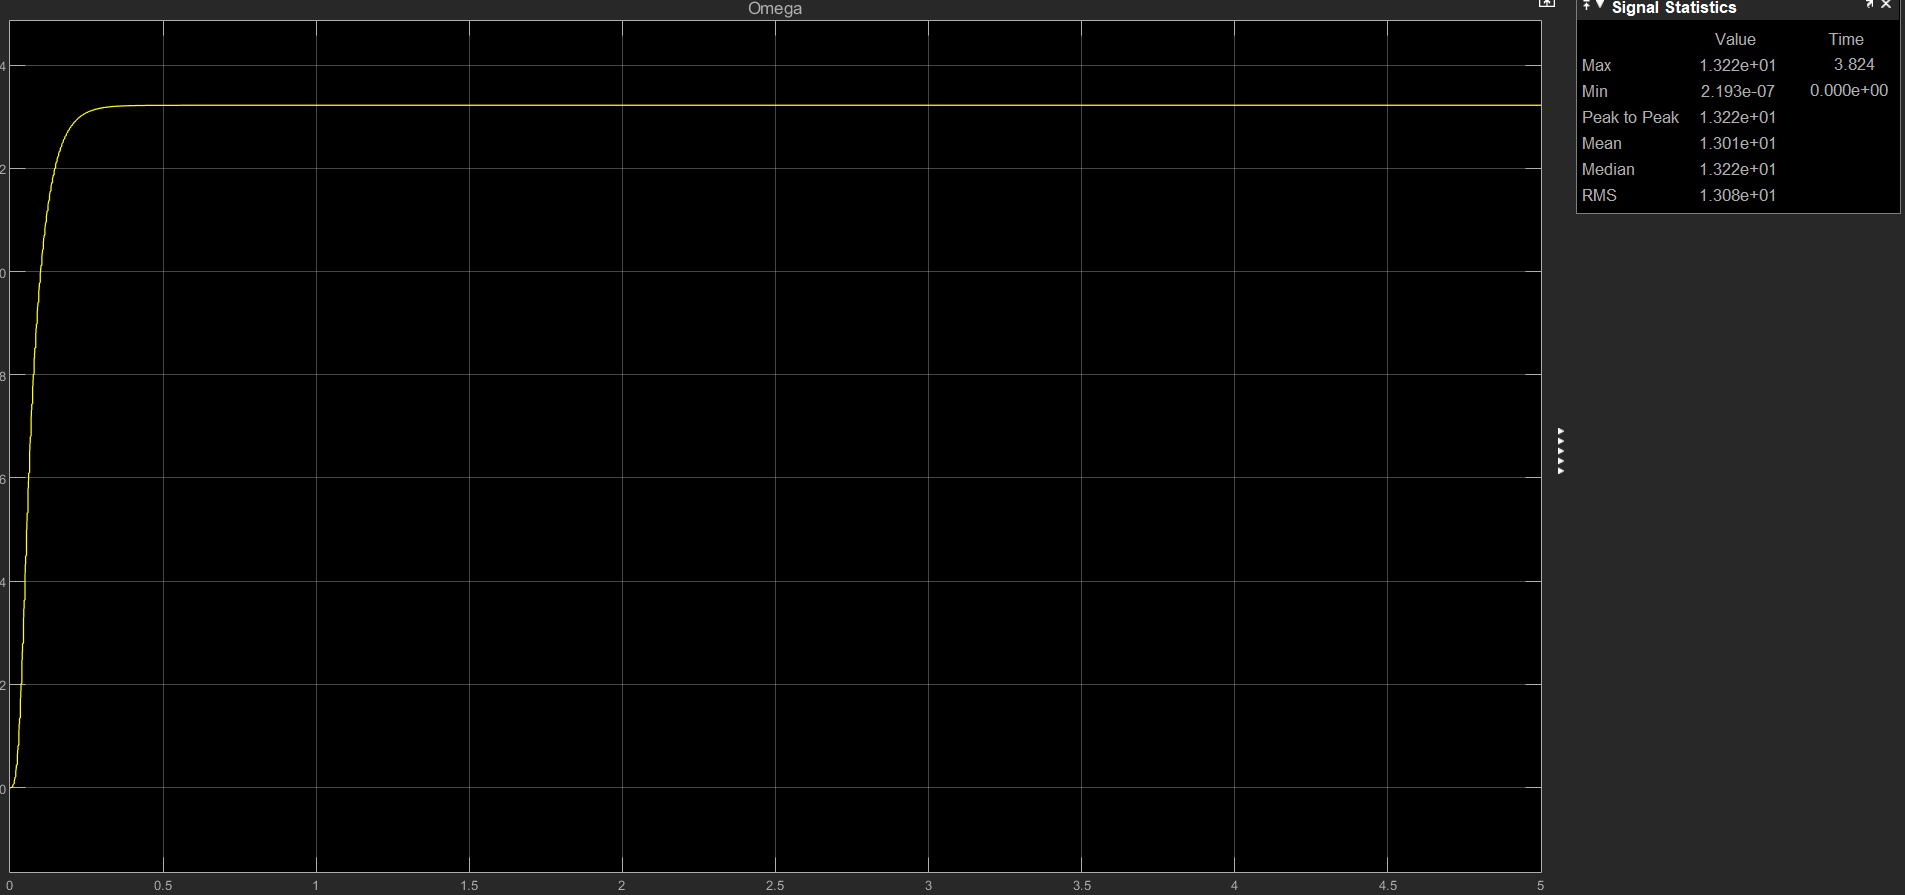

Figure 6 : scope is used for measuring the maximum angular velocity at maximum voltage

    From figure 6, the maximum angular velocity at maximum voltage is measured at 13.22 $\left(\textrm{rad}/s\right)$which mean we must design the controller to control angular velocity. After the controller, the maximum achievable angular velocity is 12.5 $\left(\textrm{rad}/s\right)$which satisfy the requirement.

**For the fifth requirement : the acceleration must not exceed 50 **$\left(\textrm{rad}/s^2 \right)$** at all time.**

    To test the acceleration of the system, we observe the system at the maximum condition which is the maximum traveled distance and maximum angular velocity.

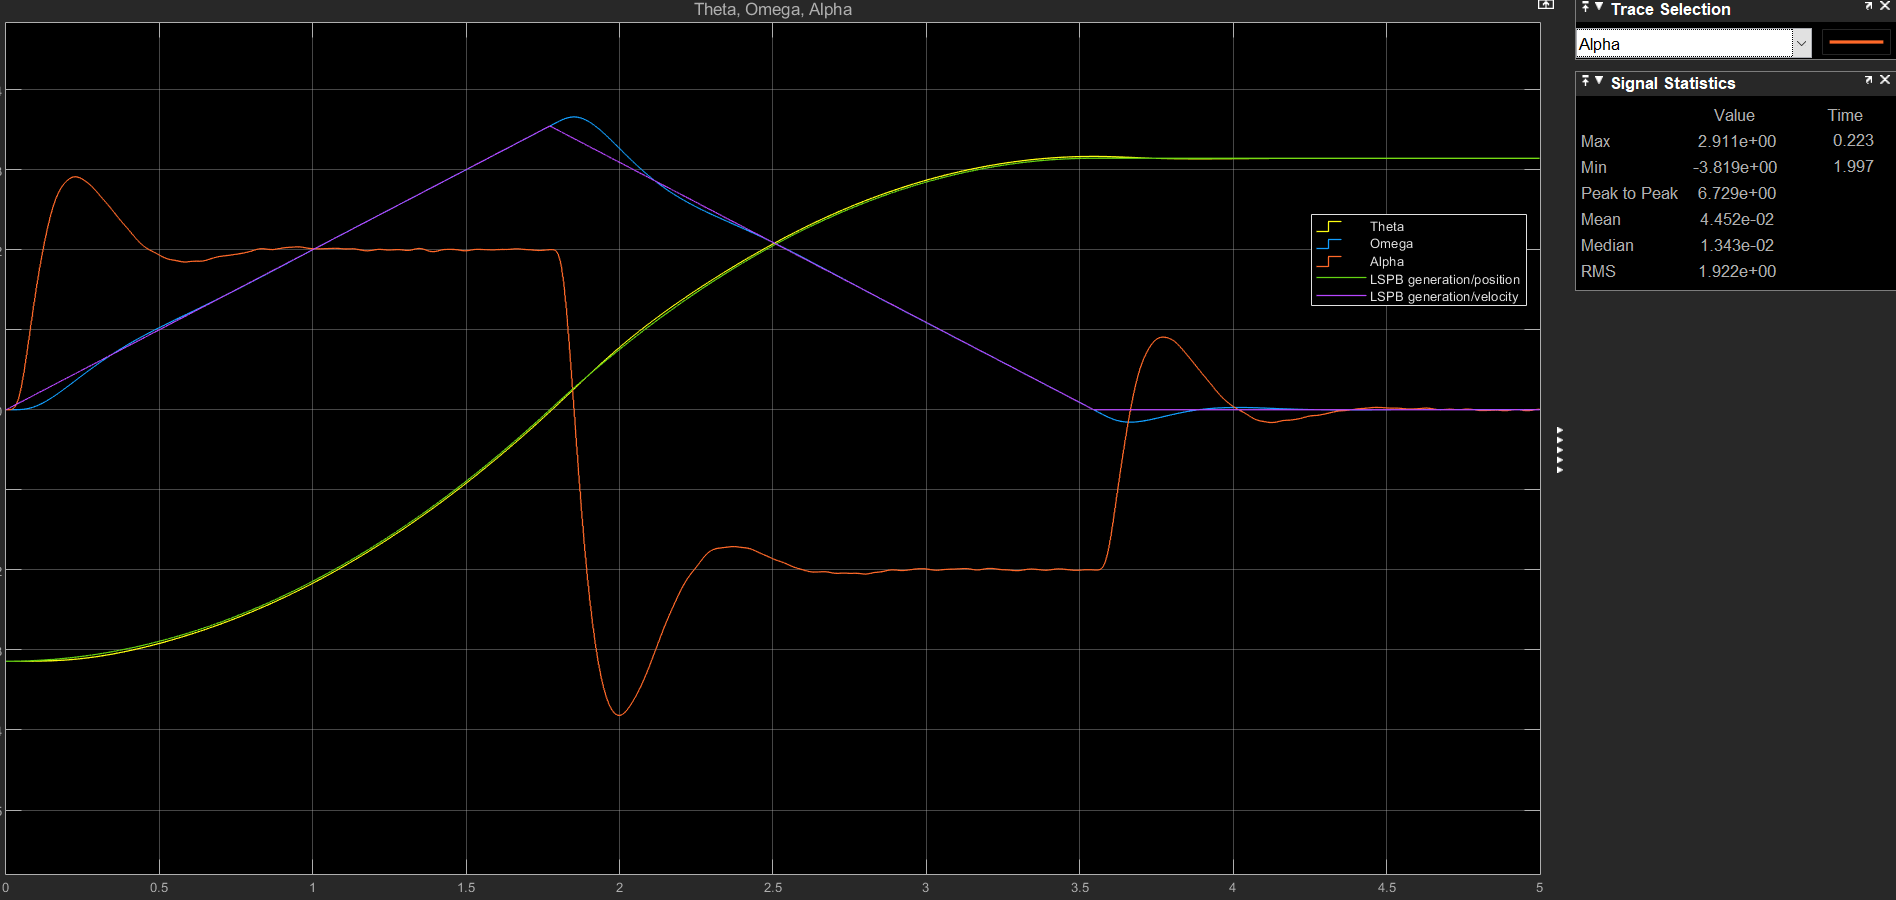

Figure 7 : Capture the response signal of angular acceleration at maximum condition

    According to figure 7, we noticed the maximum magnitude of angular acceleration at all time is 3.819 $\left(\textrm{rad}/s^2 \right)$. We can conclude that the acceleration is not exceed 50 $\left(\textrm{rad}/s^2 \right)$at all time which completes the requirement.

**For the sixth requirement : the system should reach the desired position within 5 seconds (settling time).**

    To test settling time of the system,the scope is used. We enter the maximum traveled distance, initial position = -180 degrees and final position = 180 degrees then we use scope to observe the settling time which mean the used time reaching plus or minus 2% of the final value. The result is shown in figure 8.

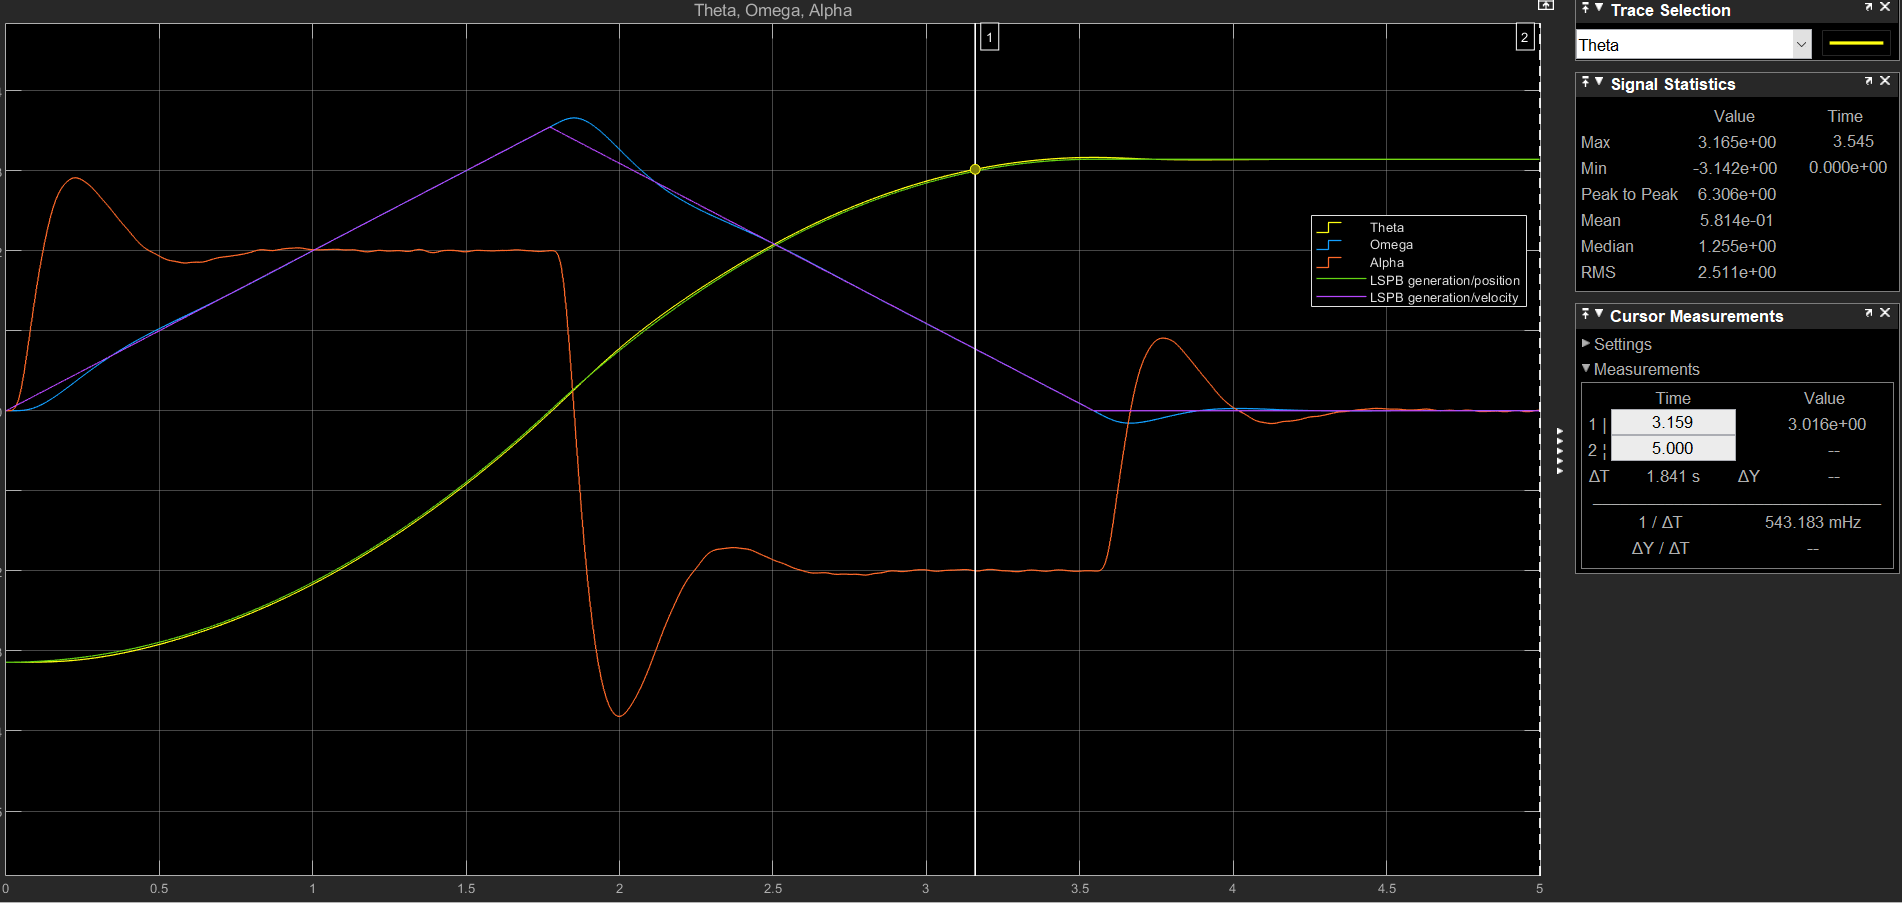

Figure 8 : Settling time 

    From the figure 8, the settling time is 3.159 seconds. We can conclude that the system can reach the desired position within 5 seconds which completes the requirement.

**For the seventh requirement : the %OS should not exceed 10%.**

    To test the %OS of the system, the scope is used to measure the peak amplitude of position to calculate the %OS. We tested by fixing initial position and final position. The results are shown below.

varNames = {'Initial Position [deg]','Final Position [deg]','%OS'};
Initial_position = [-180;-120;-160;0;0;0];
Final_position = [180;180;180;180;120;60];
OS = [0.382;0.458;0.573;0.796;1.194;2.292];
T = table(Initial_position,Final_position,OS,'VariableNames',varNames)

T = 6×3 table
    Initial Position [deg]    Final Position [deg]     %OS 
    ______________________    ____________________    _____

             -180                     180             0.382
             -120                     180             0.458
             -160                     180             0.573
                0                     180             0.796
                0                     120             1.194
                0                      60             2.292


    According to the table, we notice that the shorter traveled distance, the more %OS. After we knew the trend of changes, we tested several times to find the limit of the system. We found the limited traveled distance that can cause the %OS exceed 10%, if traveled distance is less than $\;\frac{\pi }{10\ldotp 65}\;\textrm{rad}$ or 16.9 degrees this requirement will not be completed. We can conclude that the %OS should not exceed 10% when the traveled distance is less than the limited value.

**For the eighth requirement : the maximum voltage is 12 V.**

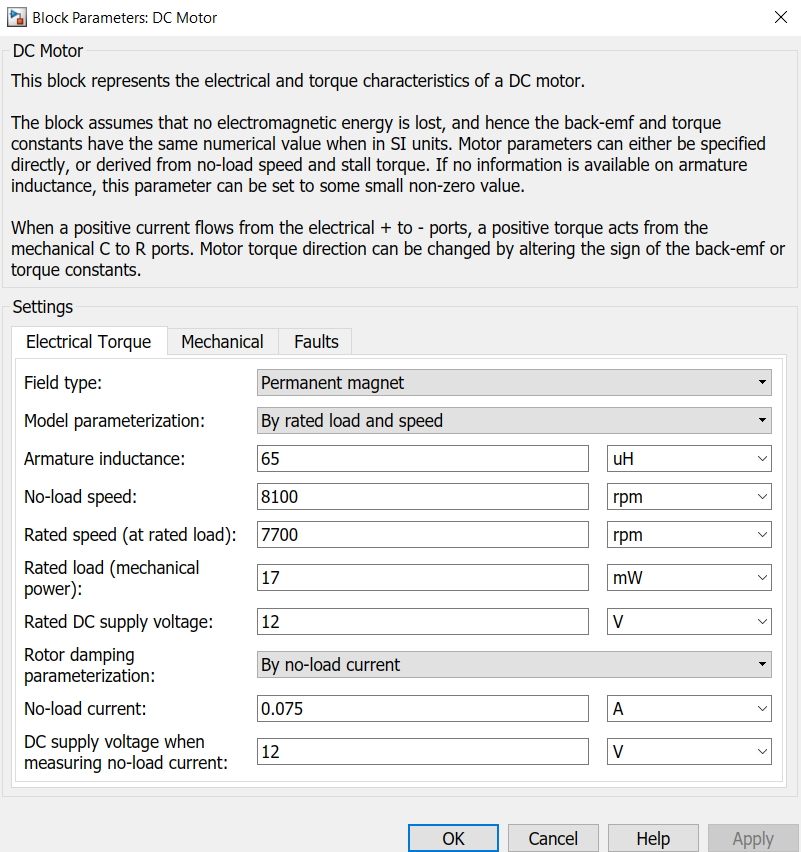

Figure 10 : DC motor's block parameter

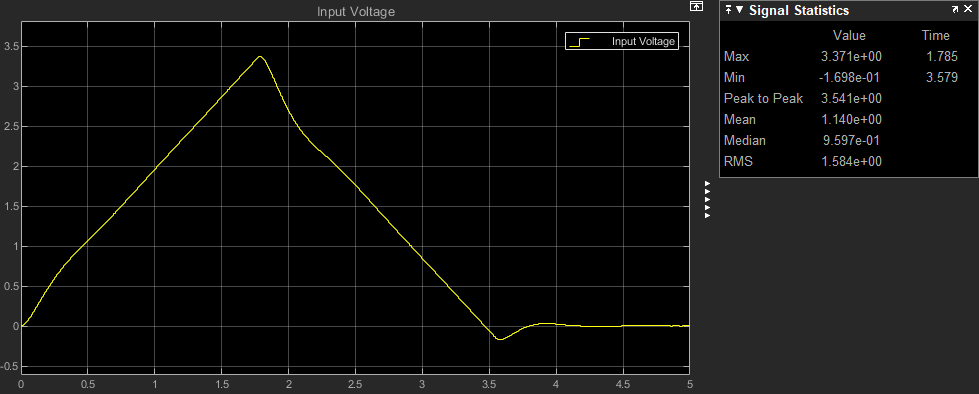

Figure 11 : applied voltage to drive motor from -180 to 180 degrees.

    According to figure 11, we can see DC supply nominal voltage is 12 V which mean the maximum voltage is 12 V too. We can conclude that the maximum voltage is 12 V which completes the requirement.

**For the ninth requirement: SNR value is 40 dB**

Due to the information in LAB2 the SNR value of this system is 80 dB which greater than the given requirement as in the figure 12.

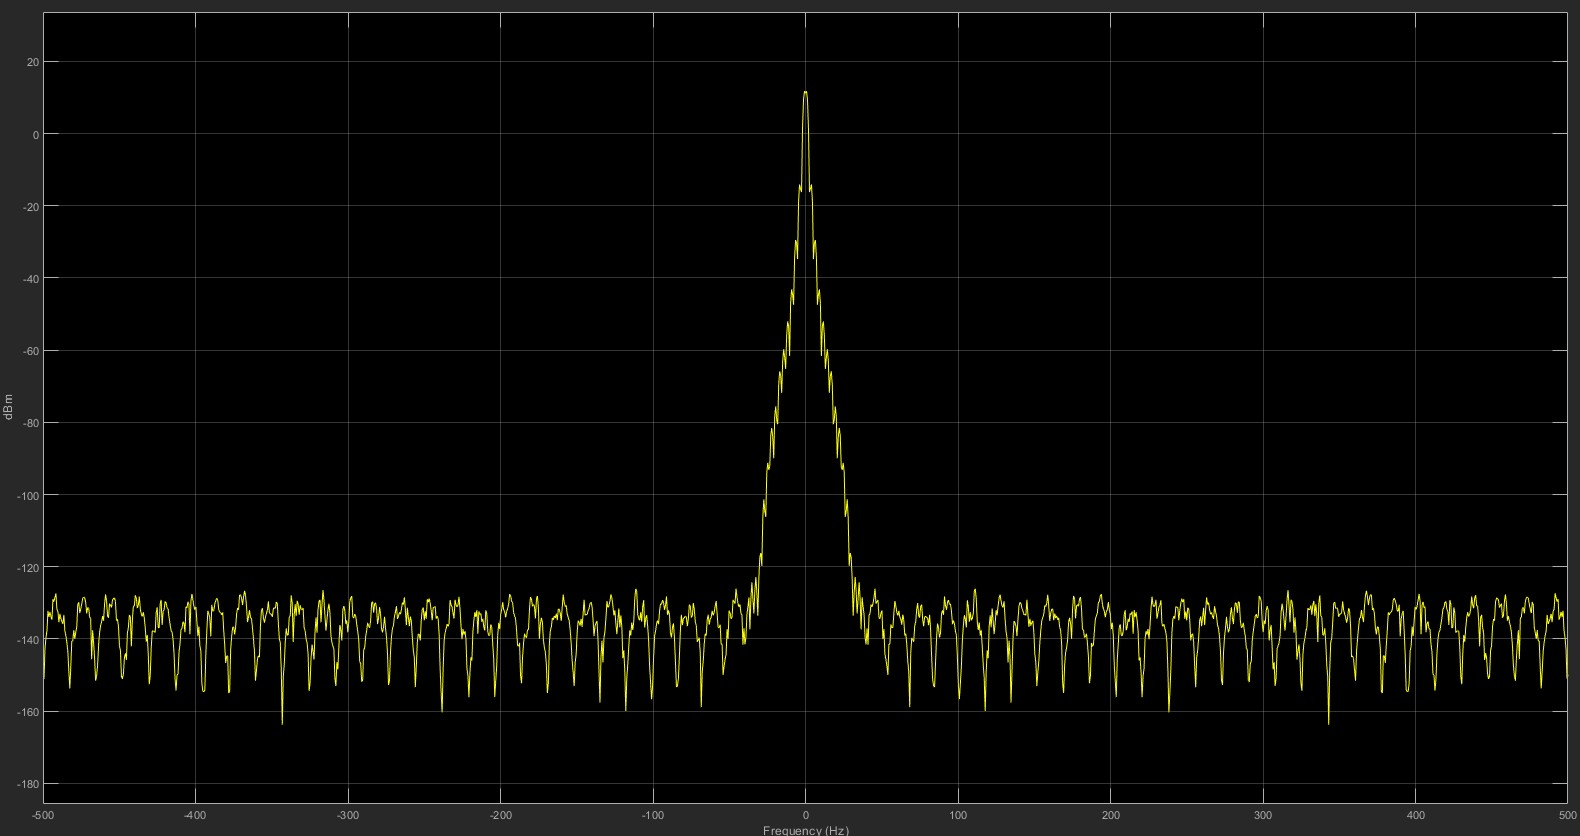

Such that, we can conclude that the SNR of this system satisfy the requirement.

**Conclusion**

      In order to create the controller, first we identified the system's characteristics as in LAB1. After we gathered all of the necessary information, the controller was built as in LAB2. To test the performance of selected lowpass filter, the noise is added into the system. Finally, to assure that the controller meets the given requirements, we verified the controller by testing and comparing it with requirements as in LAB 3. Eventually, the controller which satisfy the given requirements is built and verified.

**Note** : the traveled distance must be greater than 16.9 degrees.